# Load sample

clear
data=load("training_data.txt");
%data=load("testing_data.txt");
numfeatures=size(data,2)-1;
%end_idx=size(data,2)
%data=sortrows(data,end_idx)
%macs=load("chosen_macs.txt")
%randIndex = randperm(size(data,1));
%data=data(randIndex,:);
%sample = data(:,1:end-1);
%target =data(:,end);
%plot(sample(:,3));
sample = data(:,1:end-1);
target =data(:,end);

## Data Grouping


idx_A=find(target==0);
idx_B=find(target==1);
idx_C=find(target==2);
idx_D=find(target==3);
idx_E=find(target==4);
idx_F=find(target==5);
idx_G=find(target==6);
idx_H=find(target==7);
idx_I=find(target==8);

Acell=sample(idx_A,:);
Bcell=sample(idx_B,:);
Ccell=sample(idx_C,:);
Dcell=sample(idx_D,:);
Ecell=sample(idx_E,:);
Fcell=sample(idx_F,:);
Gcell=sample(idx_G,:);
Hcell=sample(idx_H,:);
Icell=sample(idx_I,:);


## Trimming

%Discard low samples

%Mean trimming
Acell_trimmed=zeros(size(Acell));
Bcell_trimmed=zeros(size(Bcell));
Ccell_trimmed=zeros(size(Ccell));
Dcell_trimmed=zeros(size(Dcell));
Ecell_trimmed=zeros(size(Ecell));
Fcell_trimmed=zeros(size(Fcell));
Gcell_trimmed=zeros(size(Gcell));
Hcell_trimmed=zeros(size(Hcell));
Icell_trimmed=zeros(size(Icell));

w=9;
alpha=0.2;
for i=1:numfeatures
    Acell_trimmed(:,i) = AlphaTrimMean(Acell(:,i),w,alpha);
    Bcell_trimmed(:,i) = AlphaTrimMean(Bcell(:,i),w,alpha);
    Ccell_trimmed(:,i) = AlphaTrimMean(Ccell(:,i),w,alpha);
    Dcell_trimmed(:,i) = AlphaTrimMean(Dcell(:,i),w,alpha);
    Ecell_trimmed(:,i) = AlphaTrimMean(Ecell(:,i),w,alpha);
    Fcell_trimmed(:,i) = AlphaTrimMean(Fcell(:,i),w,alpha);
    Gcell_trimmed(:,i) = AlphaTrimMean(Gcell(:,i),w,alpha);
    Hcell_trimmed(:,i) = AlphaTrimMean(Hcell(:,i),w,alpha);
    Icell_trimmed(:,i) = AlphaTrimMean(Icell(:,i),w,alpha);
end



## PMF for Cell A B C D maybe with interpolation

% P_A=[]
% for i=1:numfeatures
%     P_A=[P_A ;get_P_per_mac_per_cell(Acell(:,i),edges)];
% end
% 
% P_B=[]
% for i=1:numfeatures
%     P_B=[P_B ;get_P_per_mac_per_cell(Bcell(:,i),edges)];
% end
% P_C=[]
% for i=1:numfeatures
%     P_C=[P_C ;get_P_per_mac_per_cell(Ccell(:,i),edges)];
% end
% P_D=[]
% for i=1:numfeatures
%     P_D=[P_D ;get_P_per_mac_per_cell(Dcell(:,i),edges)];
% end

## Guasian Kernel

edges=-100:1:-1;
 [f,xi]=ksdensity(Acell_trimmed(:,16),edges);
% subplot(2,1,1)
% plot(xi,f)
% xlim([-100,0])
% subplot(2,1,2)
% histogram(Acell(:,16),edges);
% xlim([-100,0])

P_A=[];
for i=1:numfeatures
    [f,~]=ksdensity(Acell_trimmed(:,i),edges);
    P_A=[P_A ;normalize(f)];
end

P_B=[];
for i=1:numfeatures
    [f,~]=ksdensity(Bcell_trimmed(:,i),edges);
    P_B=[P_B ;normalize(f)];
end
P_C=[];
for i=1:numfeatures
    [f,~]=ksdensity(Ccell_trimmed(:,i),edges);
    P_C=[P_C ;normalize(f)];
end
P_D=[];
for i=1:numfeatures
    [f,~]=ksdensity(Dcell_trimmed(:,i),edges);
    P_D=[P_D ;normalize(f)];
end
P_E=[];
for i=1:numfeatures
    [f,~]=ksdensity(Ecell_trimmed(:,i),edges);
    P_E=[P_E ;normalize(f)];
end
P_F=[];
for i=1:numfeatures
    [f,~]=ksdensity(Fcell_trimmed(:,i),edges);
    P_F=[P_F ;normalize(f)];
end
P_G=[];
for i=1:numfeatures
    [f,~]=ksdensity(Gcell_trimmed(:,i),edges);
    P_G=[P_G ;normalize(f)];
end
P_H=[];
for i=1:numfeatures
    [f,~]=ksdensity(Hcell_trimmed(:,i),edges);
    P_H=[P_H ;normalize(f)];
end
P_I=[];
for i=1:numfeatures
    [f,~]=ksdensity(Icell_trimmed(:,i),edges);
    P_I=[P_I ;normalize(f)];
end

## Table

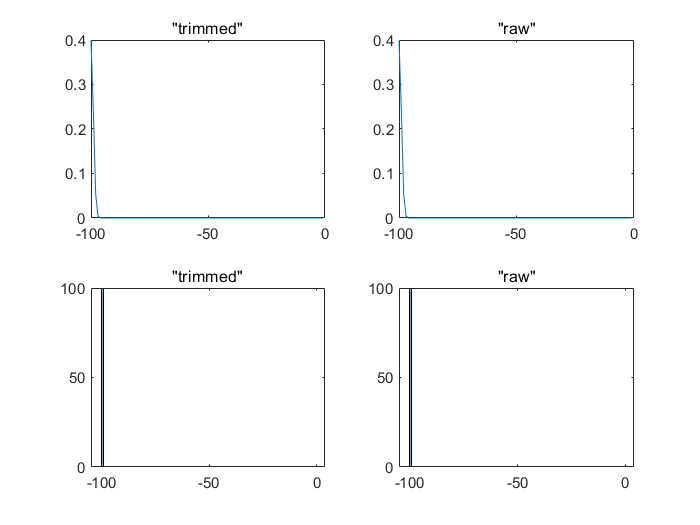

% try only one mac
% table_mac1=[P_A(1,:);P_B(1,:);P_C(1,:);P_D(1,:)];
%plot(table_mac1(2,:))
%take a look
[f1,~]=ksdensity(Acell_trimmed(:,6),edges);
[f2,~]=ksdensity(Acell(:,6),edges);
subplot(2,2,1)
plot(edges,f1)
title "trimmed"
subplot(2,2,2)
plot(edges,f2)
title "raw"
subplot(2,2,3)
histogram(Acell_trimmed(:,6),edges)
title "trimmed"
subplot(2,2,4)
histogram(Acell(:,6),edges)
title "raw"


% all maces
tables_mac=cell(1,numfeatures);
for i=1:numfeatures
    tables_mac{i}=[P_A(i,:);P_B(i,:);P_C(i,:);P_D(i,:);P_E(i,:);P_F(i,:);P_G(i,:);P_H(i,:);P_I(i,:)];
end

file_name='table_mac1.txt'

file_name = 'table_mac1.txt'

for i=1:numfeatures
    table_mac=cell2mat(tables_mac(i));
%     for j=1:4
%         sum(table_mac(4,:))
%     end
    file_name=sprintf('%s%d%s','.\mac_table\table_mac',i-1,'.txt');
    save(file_name,'table_mac','-ascii');
end


%writecell(table_mac,'table_mac1.txt') 
%TODO Baysian filtering

